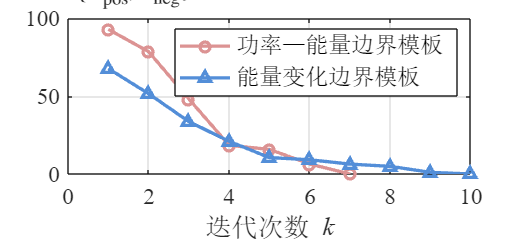

clear,clc;
load Aggs_data_1.mat
Agg1=Aggs{1};
load Aggs_data_2.mat
Agg2=Aggs{1};
colors = [220, 147, 147;...
        83, 142, 216]/255;
figure('Units','centimeter','Position',2*[5 5 7 3.3]);
plot([Agg1.model.errors],"color",colors(1,:),"LineWidth",2,'Marker','o')
hold on 
plot([Agg2.model.errors],"color",colors(2,:),"LineWidth",2,'Marker',"^")
ylabel('$\max{\{d_{\rm{pos}}^{(k)},d_{\rm{neg}}^{(k)}\}}$/kW','Interpreter',"latex",'Rotation',1,'Position',[1.6,105])
xlabel('\fontname{宋体}迭代次数\fontname{Times New Roman}\it k')
set(gca,'FontName','Times New Roman','FontSize',14)
legend({'\fontname{宋体}功率—能量边界模板','\fontname{宋体}能量变化边界模板'}, ...
    'Location',"northeast",'FontSize',14)
grid on

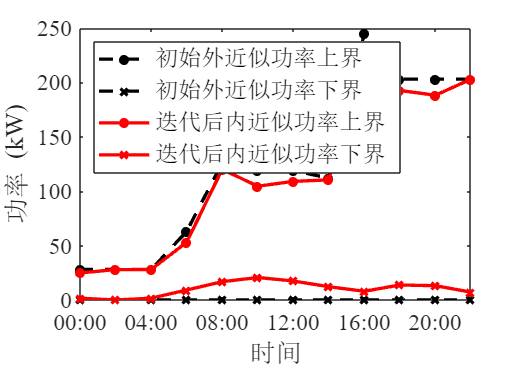

clear,clc,clf;
load b_without_redundacy.mat
load Aggs_data_1.mat
T = 12;
deltaT = 2;
Pmax_inner = b(1:T)/deltaT;
Pmin_inner = -b(T+1:2*T)/deltaT;
Emax_inner = b(2*T+1:3*T);
Emin_inner = -b(3*T+1:4*T);

Pmax0 = sum(Aggs{1, 1}.bounds.pmax,2)/deltaT;
Pmin0 = sum(Aggs{1, 1}.bounds.pmin,2)/deltaT;
Emax0 = sum(Aggs{1, 1}.bounds.emax,2);
Emin0 = sum(Aggs{1, 1}.bounds.emin,2);
figure('Units','centimeter','Position',2*[5 5 7 5]);
hold on;
plot(hours(0:2:23),Pmax0,'--*','color','k','LineWidth',2);
plot(hours(0:2:23),Pmin0,'--x','color','k','LineWidth',2);
plot(hours(0:2:23),Pmax_inner,'-*','color',[1,0,0],'LineWidth',2);
plot(hours(0:2:23),Pmin_inner,'-x','color',[1,0,0],'LineWidth',2);
xtickformat('hh:mm')
xticks([hours(0:4:20)])
xlim([0,hours(22)])
set(gca,'FontName','Times New Roman');
xlabel('\fontname{宋体}时间');
ylabel('\fontname{宋体}功率 \fontname{Times New Roman}(kW)')
%ylabel('$Power$/kW','Rotation',0,'Position',[-3,1.03*max(yticks)],'interpreter','latex','HorizontalAlignment','left');
legend({'\fontname{宋体}初始外近似功率上界', ...
    '\fontname{宋体}初始外近似功率下界', ...
    '\fontname{宋体}迭代后内近似功率上界', ...
    '\fontname{宋体}迭代后内近似功率下界'},"FontSize",14, ...
   'Location','northwest' )
set(gca,'FontName','Times New Roman','FontSize',14)
box on;

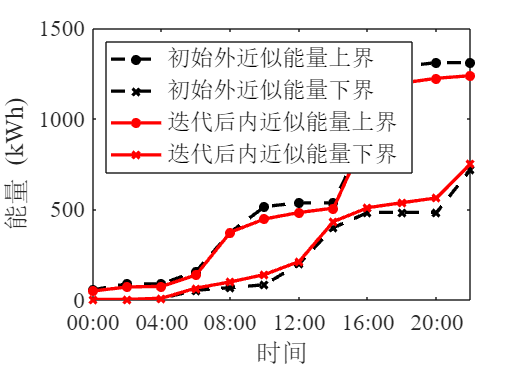


figure('Units','centimeter','Position',2*[5 5 7 5]);
hold on;
plot(hours(0:2:23),Emax0,'--*','color','k','LineWidth',2);
plot(hours(0:2:23),Emin0,'--x','color','k','LineWidth',2);
plot(hours(0:2:23),Emax_inner,'-*','color',[1,0,0],'LineWidth',2);
plot(hours(0:2:23),Emin_inner,'-x','color',[1,0,0],'LineWidth',2);
xtickformat('hh:mm')
xticks([hours(0:4:20)])
xlim([0,hours(22)])
set(gca,'FontName','Times New Roman');
xlabel('\fontname{宋体}时间');
ylabel('\fontname{宋体}能量 \fontname{Times New Roman}(kWh)')
%ylabel('$Power$/kW','Rotation',0,'Position',[-3,1.03*max(yticks)],'interpreter','latex','HorizontalAlignment','left');
legend({'\fontname{宋体}初始外近似能量上界', ...
    '\fontname{宋体}初始外近似能量下界', ...
    '\fontname{宋体}迭代后内近似能量上界', ...
    '\fontname{宋体}迭代后内近似能量下界'},"FontSize",14, ...
   'Location','northwest' )
set(gca,'FontName','Times New Roman','FontSize',14)
box on;